%% S
% 
% 
% 
% tep 1: Load & Understand Dataset
%% Step 1.2: Extract Simulation Signals
clear server
SOC = 0;
SOH = 0;
TEMP = 0;

%% Step 1.1: Load the dataset (CSV)

clc;
clear;

% Path to dataset
dataPath = "C:\Users\ponno\OneDrive\Desktop\line_follower_battery_digital_twin\data\data.csv";

% Read CSV file
data = readtable(dataPath);

% Display column names
disp("Columns in dataset:");

Columns in dataset:


disp(data.Properties.VariableNames);

    {'Voltage_measured'}    {'Current_measured'}    {'Temperature_measured'}    {'Current_charge'}    {'Voltage_charge'}    {'Time'}    {'Capacity'}    {'id_cycle'}    {'type'}    {'ambient_temperature'}    {'time'}    {'Battery'}




% Preview first few rows
head(data)

    Voltage_measured    Current_measured    Temperature_measured    Current_charge    Voltage_charge     Time     Capacity    id_cycle        type         ambient_temperature    time     Battery 
    ________________    ________________    ____________________    ______________    ______________    ______    ________    ________    _____________    ___________________    ____    _________

         3.9749             -2.0125                24.389               1.9982            3.062         35.703     1.8565        1        {'discharge'}            24             2008    {'B0005'}
   

%% Step 1.2: Extract data for SIMULATION mode

% Use only DISCHARGE data
dischargeData = data(strcmp(data.type, 'discharge'), :);

% Extract required signals
V_sim = dischargeData.Voltage_measured;         % Voltage (V)
I_sim = abs(dischargeData.Current_measured);    % Current (A) – make positive
T_sim = dischargeData.Temperature_measured;     % Temperature (°C)

% Optional time vector (not mandatory for simulation)
if any(strcmp(dischargeData.Properties.VariableNames, 'Time'))
    t_sim = dischargeData.Time;
else
    t_sim = (1:length(V_sim))';
end

% Display confirmation
fprintf("Simulation data loaded:\n");

Simulation data loaded:


fprintf("Samples: %d\n", length(V_sim));

Samples: 169766


%% Step 1.2 – Verify extracted simulation data

V_sim(1:5)

ans =     3.9749
    3.9517
    3.9344
    3.9201
    3.9079


I_sim(1:5)

ans =     2.0125
    2.0140
    2.0111
    2.0130
    2.0144


T_sim(1:5)

ans =    24.3891
   24.5448
   24.7314
   24.9098
   25.1059


%% Step 2.1: Battery SOC Model (500 mAh)
% Battery parameters
BatteryCapacity_Ah = 0.5;   % 500 mAh
Ts_sim = 1;                 % 1 second (simulation assumption)

% Initial SOC
SOC_sim = 100;

% Preallocate SOC array
SOC_sim_history = zeros(length(I_sim),1);

for k = 1:length(I_sim)
    % Coulomb counting SOC update
    SOC_sim = SOC_sim - (I_sim(k) * Ts_sim / 3600) / BatteryCapacity_Ah * 100;
    
    % Limit SOC
    SOC_sim = max(0, min(100, SOC_sim));
    
    SOC_sim_history(k) = SOC_sim;
end

disp("SOC model simulation completed");

SOC model simulation completed


%% Verify SOC values
SOC_sim_history(1:10)

ans =    99.8882
   99.7763
   99.6646
   99.5527
   99.4408
   99.3291
   99.2170
   99.1051
   98.9933
   98.8814


%% Step 2.2: Battery SOH Model
% Initial SOH
SOH_sim = 100;

% Degradation factor (small on purpose)
degradation_factor = 0.0005;

SOH_sim_history = zeros(length(I_sim),1);

for k = 1:length(I_sim)
    SOH_sim = SOH_sim - degradation_factor * abs(I_sim(k));
    SOH_sim = max(0, SOH_sim);
    
    SOH_sim_history(k) = SOH_sim;
end

disp("SOH model simulation completed");

SOH model simulation completed


SOH_sim_history(1:10)

ans =    99.9990
   99.9980
   99.9970
   99.9960
   99.9950
   99.9940
   99.9930
   99.9919
   99.9909
   99.9899


%% Step 2.3: Battery Thermal Model
% Thermal parameters
R_th = 2.0;           % Thermal resistance
AmbientTemp = mean(T_sim);   % Use dataset ambient temperature

TEMP_sim_history = zeros(length(I_sim),1);

for k = 1:length(I_sim)
    % Heat generation ~ I^2 * R
    TEMP_sim_history(k) = AmbientTemp + (I_sim(k)^2 * R_th);
end

disp("Thermal model simulation completed");

Thermal model simulation completed


TEMP_sim_history(1:10)

ans =    40.0860
   40.0977
   40.0749
   40.0899
   40.1011
   40.0786
   40.1302
   40.0909
   40.0911
   40.0901


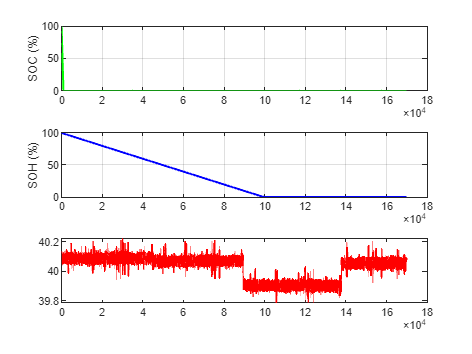

%% Step 2.4: Plot SOC, SOH, Thermal (Simulation)
figure
subplot(3,1,1)
plot(SOC_sim_history,'g','LineWidth',1.5)
ylabel('SOC (%)'); grid on

subplot(3,1,2)
plot(SOH_sim_history,'b','LineWidth',1.5)
ylabel('SOH (%)'); grid on

subplot(3,1,3)
plot(TEMP_sim_history,'r','LineWidth',1.5)

%% Step 3.1: Manual Mode Selection (Simulation / Real-Time)

% USER MANUAL SELECTION
% "SIMULATION"  → CSV dataset
% "REALTIME"    → ESP32 Wi-Fi

MODE = "SIMULATION" ;     % Change manually during demo

disp("Current Mode:");

Current Mode:


disp(MODE);

SIMULATION


if MODE == "SIMULATION"
    disp("Using SIMULATION data");

    Voltage_input = V_sim;
    Current_input = I_sim;

elseif MODE == "REALTIME"
    disp("Using REAL-TIME data");

   
end

Using SIMULATION data


REAL TIME

%% ================= REAL-TIME DIGITAL TWIN =================

if MODE == "REALTIME"

    %% 🔹 START TCP SERVER
    clear server;
    server = tcpserver("0.0.0.0", 8081);

    disp("======================================");
    disp("✅ MATLAB SERVER STARTED");
    disp("📡 Waiting for ESP32 data...");
    disp("======================================");

    %% 🔹 INITIALIZE VARIABLES (IMPORTANT)
    Voltage = [];
    Current = [];
    t = [];

    % Initial dummy values (avoid Simulink errors)
    Voltage_ts = timeseries(0,0);
    Current_ts = timeseries(0,0);

    assignin('base','Voltage_ts',Voltage_ts);
    assignin('base','Current_ts',Current_ts);

    k = 0;

    %% 🔹 REAL-TIME LOOP
    while true

        if server.NumBytesAvailable > 0

            % Read incoming data
            rawData = readline(server);

            % Show raw data (debug)
            disp("📥 Raw: " + rawData);

            % Extract values using regex
            tokens = regexp(rawData, ...
                'V=(\d+\.?\d*)&I=(-?\d+\.?\d*)', 'tokens');

            if ~isempty(tokens)

                V = str2double(tokens{1}{1});
                I = str2double(tokens{1}{2});

                % Validate values
                if ~isnan(V) && ~isnan(I)

                    %% 🔥 DISPLAY VALUES IN MATLAB
                    fprintf("⚡ Voltage = %.2f V | Current = %.2f A\n", V, I);

                    %% 🔹 STORE DATA
                    k = k + 1;

                    t(k) = k;              % time step
                    Voltage(k) = V;
                    Current(k) = I;

                    %% 🔹 UPDATE TIMESERIES (IMPORTANT)
                    Voltage_ts.Data = Voltage;
                    Voltage_ts.Time = t;

                    Current_ts.Data = Current;
                    Current_ts.Time = t;

                    %% 🔹 SEND TO SIMULINK
                    assignin('base','Voltage_ts',Voltage_ts);
                    assignin('base','Current_ts',Current_ts);

                    %% 🔥 FORCE SIMULINK UPDATE
                    try
                        set_param('battery_hybrid_digital_twin', ...
                                  'SimulationCommand','update');
                    catch
                        % Ignore if model not running
                    end

                end
            end
        end

        pause(0.05);   % Smooth update
    end
end

SIMULATION

if MODE == "SIMULATION"

    data = readtable("C:\Users\ponno\OneDrive\Desktop\line_follower_battery_digital_twin\data\data.csv");

    Voltage = data.Voltage_measured;
    Current = data.Current_measured;

    Ts = 1;
    t = (0:length(Voltage)-1)' * Ts;

    Voltage_ts = timeseries(Voltage, t);
    Current_ts = timeseries(Current, t);

    assignin('base','Voltage_ts',Voltage_ts);
    assignin('base','Current_ts',Current_ts);

end